clear all
close all
clc


# Planartransformer

## Needed specifications

Three windings with one primary winding $N_1
$ and two secondary windings $N_2,  N_3
$. Between the secondary and primary side is an isolation of $\geq 2kV

$ needed, between $N_2$ and $N_3

$ the isolation only needs to sustain $35V
$.

The turn ratios of the winding need to be $\frac {N_1}{N_2}=\frac {1}{1}$ and $\frac {N_1}{N_3}=\frac {3}{2}$.

The core can have a maximum width of$<\frac{45mm-6,4mm}2$ to mantain the proper Isolation of the power supply.

Losses should be minimized. To decrease the inductor size the switching frequency of the input will be increased to $1,2MHz
$. The amplitude of the switching input will be 15V and resemble a square wave. The driver chip for this inductor will be UCC25800-Q1.

([UCC25800-Q1 Ultra-low EMI Transformer Driver for Isolated Bias Supplies datasheet (Rev. C](https://www.ti.com/lit/ds/symlink/ucc25800-q1.pdf?ts=1746682374622&ref_url=https%253A%252F%252Fwww.ti.com%252Fproduct%252FUCC25800-Q1)

f = 1.2e6

f =      1200000

### Core propsal:

#### 1)

[ferrite_mz_sw_planar_en.pdf](https://product.tdk.com/system/files/dam/doc/product/ferrite/ferrite/ferrite-core/catalog/ferrite_mz_sw_planar_en.pdf)

+high inductance ($A_L
$)

-high core losses at high frequency not suitable for more than 500kHz

-inductance decreases at high frequency

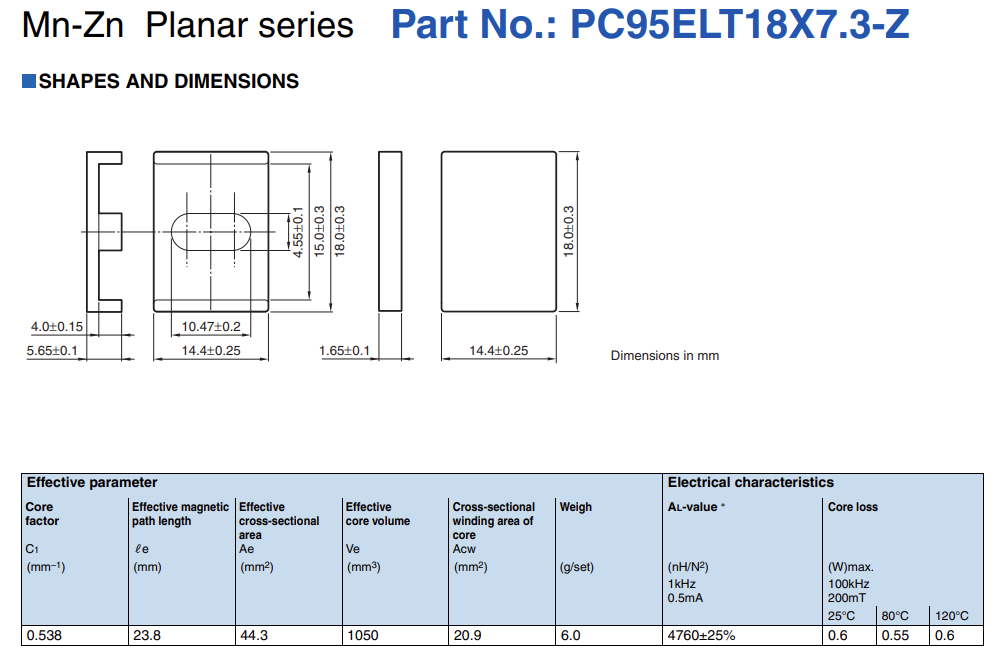

#### 2)

[Ferrites and accessories - ELP 18/4/10 with I 18/2/10 - Cores and accessories (with and without clamp recess)](https://product.tdk.com/system/files/dam/doc/product/ferrite/ferrite/ferrite-core/data_sheet/80/db/fer/elp_18_4_10.pdf)

(B66283G0000X608)

+low core loss up to 2MHz

-lower Inductance ($A_L
$)

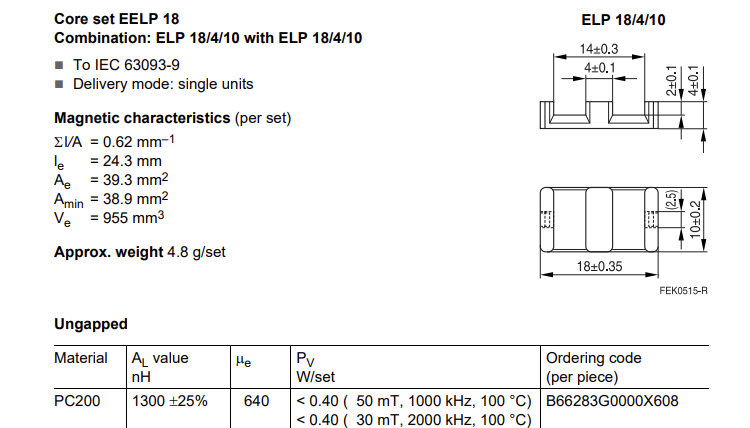

### Stackup Proposal:

Copper thickness $[\sigma_{cu}]$:

"This analysis shows that it is very important that the skin depth in the substrate should be greater than the thickness of the substrate" (transformers_wiley_book_ch9)

"The PCB **trace** is flat, and the copper **thickness** is generally 1oz/2oz. By calculation, at frequencies less than 14MHz, the skin depth of copper is less than half of the **thickness** of the PCB copper." ([Principle of Planar Transformers and PCB Design](https://en.sunshinepcb.com/news/Industry/64.html#:~:text=The%20PCB%20trace%20is%20flat%2C%20and%20the%20copper,half%20of%20the%20thickness%20of%20the%20PCB%20copper.))


$$\delta=\sqrt{\frac{\rho}{\pi\cdot f\cdot \mu}}$$


mu0 = 4*pi*1e-7

mu0 =      1.256637061435917e-06

ds = ((16.78e-9)/(pi*f*0.999991*mu0))^(1/2)

ds =      5.951513748586182e-05


$$\delta=59,52\mu m$$



$$\sigma_{cu}<\delta(59,52\mu m) ?$$


#### 1)

Sandwich style stackup: The primary in the center and the secondary on the top and bottom. Two cores can provide sufficient isolation. The voltage break down of FR4 is $20\frac{kV}{mm}
$.

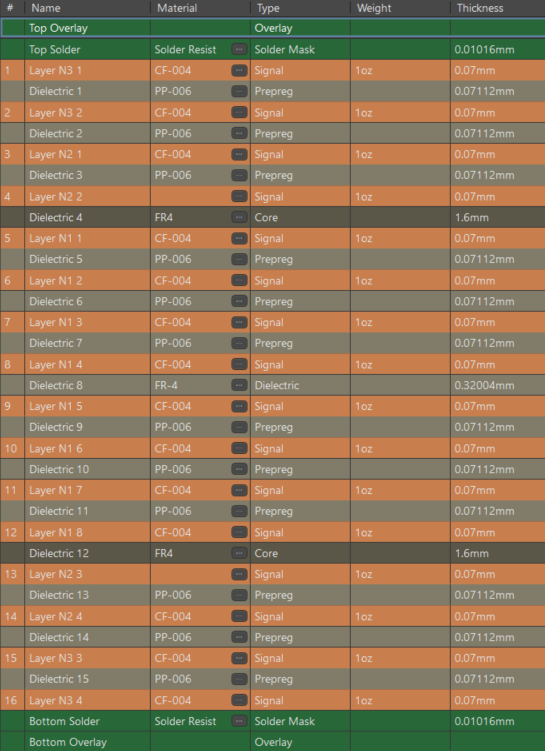

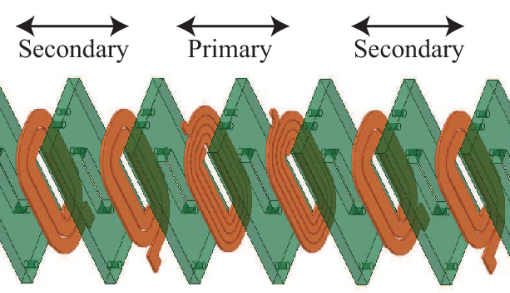

[Planar transformer winding technique for reduced capacitance in LLC power converters | Semantic Scholar](https://www.semanticscholar.org/paper/Planar-transformer-winding-technique-for-reduced-in-Saket-Shafiei/ca5e0f50022deeedb86d3f12380e0415ff3f87bb#extracted)

#### 2)

Two 8-layer PCB are stacked to save manufactering cost. Each PCB only has one core. If stacked it is similar to proposal-1 but is more cost effective and can be manufactured by a broader range of manufactures. For both proposals FR4 sheets with a thickness of 0.3mm-0.4mm can be placed between the pcb and ferritecore to improve isolation between the core and the windings.

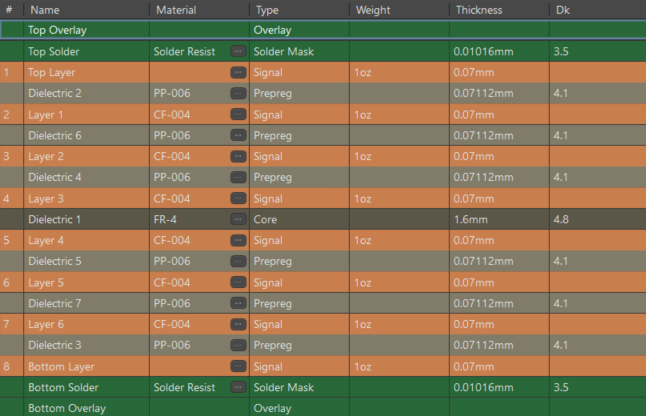

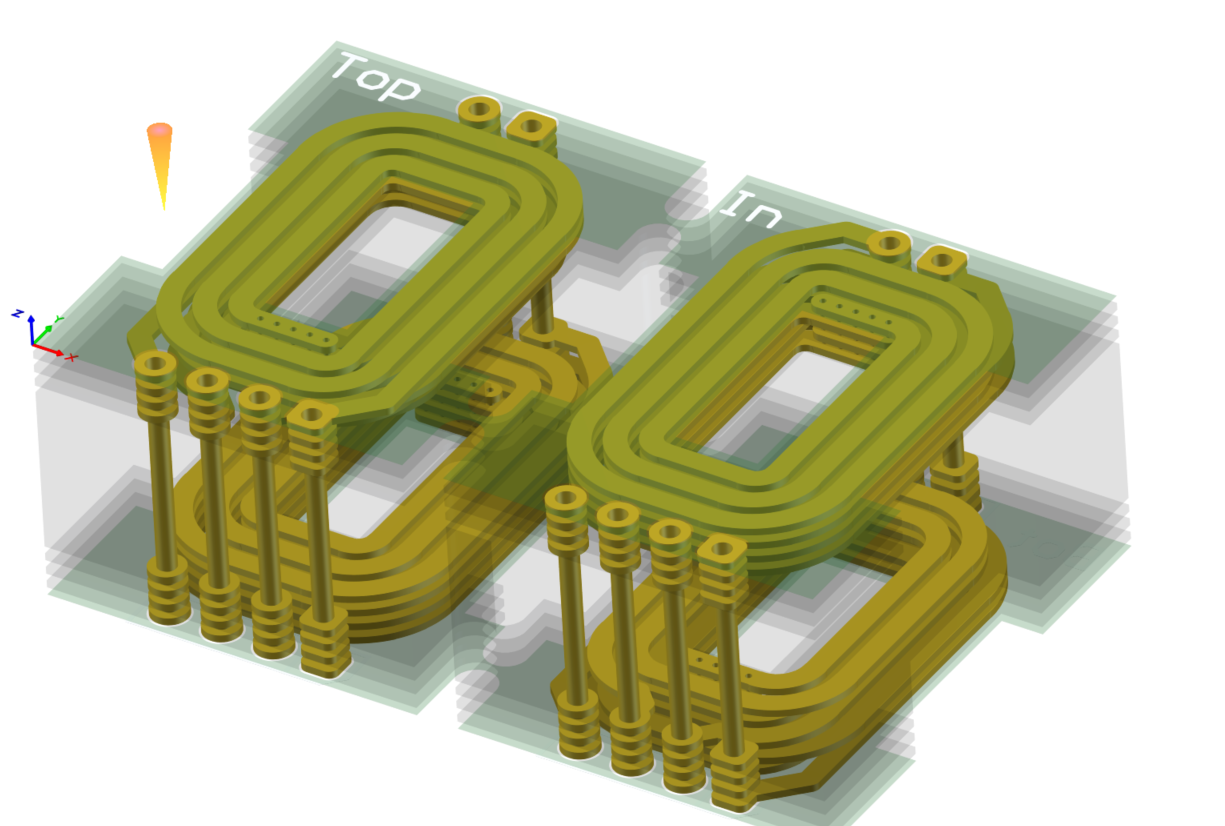

### Number of turns

The input frequency will be 1.2MHz therfore a lower nuber of turns can be used. With a lower number of turns the size of the core can be reduced and the leakage inductance can be decreased. Therfore the coupling coefficient gets higher.

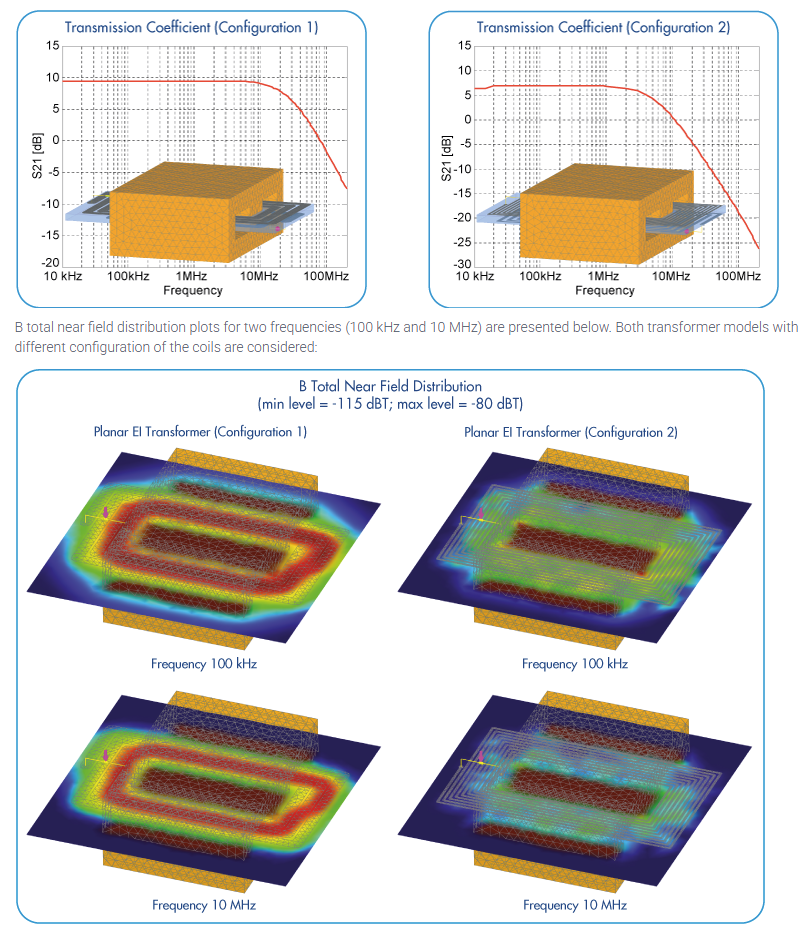

[Modeling of Planar Transformer with Ferrite EI Core - EMCoS](https://emcos.com/?application-examples=modeling-of-planar-transformer-with-ferrite-ei-core-2)

#### Propsal: 


$$N_1\rightarrow6
$$


N1 = 6

N1 =      6


$$N_2\rightarrow6
$$


N2 = 6

N2 =      6


$$N_3\rightarrow4

$$


N3 = 4

N3 =      4


$$f_{SW}=1,2MHz
$$


f = 530e3

f =       530000

Trace width $(w_{trace} \rightarrow 0,7mm)$

wtra = 0.7e-3

wtra =      7.000000000000000e-04

Average turn lengh $(l_{turn}\rightarrow 45mm)
$

ltrn = 45e-3

ltrn =      4.500000000000000e-02


$$\sigma_{cu}=70\mu m$$


dcu = 70e-6

dcu =      6.999999999999999e-05


$$\sigma_{core}=1,3mm$$


dcore = 1.3e-3

dcore =      1.300000000000000e-03

#### **Core: 2*(B66283G0000X608)+2*(**B65804P2204X000)


$$l_e=24,3mm
$$


le = 24.3e-3

le =      2.430000000000000e-02


$$A_e=39.3mm²
$$


Ae = 39.3e-6

Ae =      3.930000000000000e-05


$$V_e=955mm³
$$


Ve = 955e-9

Ve =      9.550000000000000e-07


$$A_L=1300 \frac{nH}{N²}\pm25\%$$


Al = 1300e-9

Al =      1.300000000000000e-06

mu = Al/Ae*le

mu =      8.038167938931298e-04

mur = mu/mu0

mur =      6.396570804418542e+02


$$B_{sat}(100\degree C)=0,42T
$$


Bsat = 0.42

Bsat =      4.200000000000000e-01


$$P_V<0,4\frac{mW}{g}
$$


Pv =0.4

Pv =      4.000000000000000e-01


$$\mu_e=640$$


mure = 640

mure =    640


$$\rho_{NiZn}\approx4,7\frac{g}{cm³}$$


pnizn = 4.7*(1e-3/1e-6)

pnizn =      4.700000000000001e+03

#### Calculation


$$L=A_L*N²$$



$$L_1\rightarrow46,8\mu H
$$


L1 = Al * N1^2

L1 =      4.680000000000000e-05


$$L_2\rightarrow46,8\mu H

$$


L2 = Al * N2^2

L2 =      4.680000000000000e-05


$$L_3\rightarrow20,8\mu H


$$


L3 = Al * N3^2

L3 =      2.080000000000000e-05


$$I_{sat}=\frac{B_{sat}\cdot A_e}{\mu_0\cdot N}$$


Isat = Bsat*Ae/(mu0*N1)

Isat =      2.189176242229021e+00


$$I{sat}=2,189A$$



$$P_{core}=P_v\cdot m_{core}$$



$$m_{core}\approx V_e\cdot\rho_{NiZn}
$$


Pcore = Pv * Ve * pnizn

Pcore =      1.795400000000000e-03


$$P_{core}\approx1,7954mW$$



$$L_{Leak}\approx 2,2\mu H
$$


Lleak1 = 2.2e-6

Lleak1 =      2.200000000000000e-06

Lleak2 = 2.2e-6

Lleak2 =      2.200000000000000e-06

Lleak3 = 0.978e-6

Lleak3 =      9.780000000000000e-07


$$k=\sqrt{1-\frac{L_{Leak}}{L_1}}$$


k1 = (1-Lleak1/L1)^(1/2)

k1 =      9.762128113231525e-01

k2 = (1-Lleak2/L2)^(1/2)

k2 =      9.762128113231525e-01

k3 = (1-Lleak3/L3)^(1/2)

k3 =      9.762073392629095e-01


$$k\approx 0,976$$



$$C_{parasitc}=\epsilon_{r (FR4)}\cdot\epsilon_0 \cdot\frac{A}{d}$$


e0 = 8.854e-12

e0 =      8.853999999999999e-12

er = 4.4

er =      4.400000000000000e+00

Acap12 = ltrn * wtra * N2/2

Acap12 =      9.449999999999999e-05

Acap13 = ltrn * wtra * N3/2

Acap13 =      6.300000000000000e-05

Acap23 = ltrn * wtra * N3/2

Acap23 =      6.300000000000000e-05

% * 2 because of the sandwich style layout
Cpar12 = er * e0 * Acap12/dcore * 2

Cpar12 =      5.663835692307691e-12

Cpar13 = er * e0 * Acap13/dcore * 2

Cpar13 =      3.775890461538462e-12

% there is no core between N2 and N3
Cpar23 = er * e0 * Acap13/70e-6 * 2

Cpar23 =      7.012368000000000e-11


$$R_{cu}=\rho\cdot\frac{l}{A}$$


%the last number is the number of parallel windings
rhocu = 1.68e-8

rhocu =      1.680000000000000e-08

RN1 = rhocu * (ltrn * N1) / (dcu * wtra) / 4

RN1 =      2.314285714285715e-02

RN2 = rhocu * (ltrn * N2) / (dcu * wtra) / 2

RN2 =      4.628571428571430e-02

RN3 = rhocu * (ltrn * N3) / (dcu * wtra) / 2

RN3 =      3.085714285714286e-02


$$C_{in}=\frac{1}{\omega²L_1}

$$


%Cin = 1/((2*pi*f*1.1)^2*Lleak1)
Cin = 680e-9

Cin =      6.799999999999999e-07


$$C_r =\frac{1}{\left(4\cdot \pi ²\cdot L_r \cdot f_r ²\right)}$$


Cr1 = 1/(4*pi^2*2e-6*(f*1.1)^2)

Cr1 =      3.726260030566515e-08

% Cr1 = 1/(4*pi^2*((Lleak2+Lleak1)/2)*(f*1.1)^2)
%Cr1 = 1/(4*pi^2*Lleak2*(f)^2)
%Cr1 = 4.7e-6*2
%Cr1 = 1/(4*pi^2*(Lleak2+Lleak3)*(f*1.1)^2)
Cr2 = 1/(4*pi^2*((Lleak3+Lleak1)/2)*(f*1.1)^2)

Cr2 =      4.690069264400901e-08

%Cr2 = 4.7e-6*2
%Cr2 = Cr1
Cr = 22e-9;

## Simulation

R_out = 840;
return

R_out = 1e6
out1 = sim('Planar_Transformer_sim',10e-3);

I_L1 = out1.I_L1;
I_L2 = out1.I_L2;
I_L3 = out1.I_L3;
I_out1 = out1.I_out1;
I_out2 = out1.I_out2;
U_in = out1.U_in;
U_L1 = out1.U_L1;
U_L2= out1.U_L2;
U_L3 = out1.U_L3;
U_out1 = out1.U_out1;
U_out2 = out1.U_out2;

plot(I_L1);
title('Current (Rout->1MR)');
hold on;
plot(I_L2);
plot(I_L3);
plot(I_out1);
plot(I_out2);
legend('I_{L1}','I_{L2}','I_{L3}','I_{out1}','I_{out2}');
hold off;

plot(U_L1);
title('Voltages (Rout->1MR)');
hold on;
plot(U_L2);
plot(U_L3);
plot(U_out1);
plot(U_out2);
legend('U_{L1}','U_{L2}','U_{L3}','U_{out1}','U_{out2}');
hold off;

plot(U_L1);
title('Voltages (Rout->1MR)');
hold on;
plot(U_L2);
plot(U_L3);
plot(U_out1);
plot(U_out2);
legend('U_{L1}','U_{L2}','U_{L3}','U_{out1}','U_{out2}');
hold off;
xlim([0.009998 0.01])

plot(I_L1);
title('Current (Rout->1MR)');
hold on;
plot(I_L2);
plot(I_L3);
plot(I_out1);
plot(I_out2);
legend('I_{L1}','I_{L2}','I_{L3}','I_{out1}','I_{out2}');
hold off;
xlim([0.009998 0.01])

plot(U_in);
title('Input Voltage');
xlim([0.009998 0.01])
ylim([-1.0 16.0])


R_out = 750
out2 = sim('Planar_Transformer_sim',10e-3);

I_L1 = out2.I_L1;
I_L2 = out2.I_L2;
I_L3 = out2.I_L3;
I_out1 = out2.I_out1;
I_out2 = out2.I_out2;
U_in = out2.U_in;
U_L1 = out2.U_L1;
U_L2= out2.U_L2;
U_L3 = out2.U_L3;
U_out1 = out2.U_out1;
U_out2 = out2.U_out2;

plot(I_L1);
title('Current (Rout->750R)');
hold on;
plot(I_L2);
plot(I_L3);
plot(I_out1);
plot(I_out2);
legend('I_{L1}','I_{L2}','I_{L3}','I_{out1}','I_{out2}');
hold off;

plot(U_L1);
title('Voltages (Rout->750R)');
hold on;
plot(U_L2);
plot(U_L3);
plot(U_out1);
plot(U_out2);
legend('U_{L1}','U_{L2}','U_{L3}','U_{out1}','U_{out2}');
hold off;

plot(U_L1);
title('Voltages (Rout->750R)');
hold on;
plot(U_L2);
plot(U_L3);
plot(U_out1);
plot(U_out2);
legend('U_{L1}','U_{L2}','U_{L3}','U_{out1}','U_{out2}');
hold off;
xlim([0.009998 0.01])

plot(I_L1);
title('Current (Rout->750R)');
hold on;
plot(I_L2);
plot(I_L3);
plot(I_out1);
plot(I_out2);
legend('I_{L1}','I_{L2}','I_{L3}','I_{out1}','I_{out2}');
hold off;
xlim([0.009998 0.01])

plot(U_in);
title('Input Voltage');
xlim([0.009998 0.01])
ylim([-1.0 16.0])



R_out = 150
out3 = sim('Planar_Transformer_sim',10e-3);

I_L1 = out3.I_L1;
I_L2 = out3.I_L2;
I_L3 = out3.I_L3;
I_out1 = out3.I_out1;
I_out2 = out3.I_out2;
U_in = out3.U_in,
U_L1 = out3.U_L1;
U_L2 = out3.U_L2;
U_L3 = out3.U_L3;
U_out1 = out3.U_out1;
U_out2 = out3.U_out2;

plot(I_L1);
title('Current (Rout->150R)');
hold on;
plot(I_L2);
plot(I_L3);
plot(I_out1);
plot(I_out2);
legend('I_{L1}','I_{L2}','I_{L3}','I_{out1}','I_{out2}');
hold off;

plot(U_L1);
title('Voltages (Rout->150R)');
hold on;
plot(U_L2);
plot(U_L3);
plot(U_out1);
plot(U_out2);
legend('U_{L1}','U_{L2}','U_{L3}','U_{out1}','U_{out2}');
hold off;

plot(U_L1);
title('Voltages (Rout->150R)');
hold on;
plot(U_L2);
plot(U_L3);
plot(U_out1);
plot(U_out2);
legend('U_{L1}','U_{L2}','U_{L3}','U_{out1}','U_{out2}');
hold off;

xlim([0.009998 0.01])

plot(I_L1);
title('Current (Rout->150R)');
hold on;
plot(I_L2);
plot(I_L3);
plot(I_out1);
plot(I_out2);
legend('I_{L1}','I_{L2}','I_{L3}','I_{out1}','I_{out2}');
hold off;
xlim([0.009998 0.01])

plot(U_in);
title('Input Voltage');
xlim([0.009998 0.01])
ylim([-1.0 16.0])


R_out = 30
out4 = sim('Planar_Transformer_sim',10e-3);

I_L1 = out4.I_L1;
I_L2 = out4.I_L2;
I_L3 = out4.I_L3;
I_out1 = out4.I_out1;
I_out2 = out4.I_out2;
U_in = out4.U_in,
U_L1 = out4.U_L1;
U_L2 = out4.U_L2;
U_L3 = out4.U_L3;
U_out1 = out4.U_out1;
U_out2 = out4.U_out2;

plot(I_L1);
title('Current (Rout->30R)');
hold on;
plot(I_L2);
plot(I_L3);
plot(I_out1);
plot(I_out2);
legend('I_{L1}','I_{L2}','I_{L3}','I_{out1}','I_{out2}');
hold off;

plot(U_L1);
title('Voltages (Rout->30R)');
hold on;
plot(U_L2);
plot(U_L3);
plot(U_out1);
plot(U_out2);
legend('U_{L1}','U_{L2}','U_{L3}','U_{out1}','U_{out2}');
hold off;

plot(U_L1);
title('Voltages (Rout->30R)');
hold on;
plot(U_L2);
plot(U_L3);
plot(U_out1);
plot(U_out2);
legend('U_{L1}','U_{L2}','U_{L3}','U_{out1}','U_{out2}');
hold off;
xlim([0.009998 0.01])

plot(I_L1);
title('Current (Rout->30R)');
hold on;
plot(I_L2);
plot(I_L3);
plot(I_out1);
plot(I_out2);
legend('I_{L1}','I_{L2}','I_{L3}','I_{out1}','I_{out2}');
hold off;
xlim([0.009998 0.01])

plot(U_in);
title('Input Voltage');
xlim([0.009998 0.01])
ylim([-1.0 16.0])

plot(out1.I_L1);
title('Current (L1)');
hold on;
plot(out2.I_L1);
plot(out3.I_L1);
plot(out4.I_L1);
legend('1M\Omega','750\Omega','150\Omega','30\Omega');
hold off;
xlim([0.009998 0.01])

plot(out1.I_L2);
title('Current (L2)');
hold on;
plot(out2.I_L2);
plot(out3.I_L2);
plot(out4.I_L2);
legend('1M\Omega','750\Omega','150\Omega','30\Omega');
hold off;
xlim([0.009998 0.01])

plot(out1.I_L3);
title('Current (L3)');
hold on;
plot(out2.I_L3);
plot(out3.I_L3);
plot(out4.I_L3);
legend('1M\Omega','750\Omega','150\Omega','30\Omega');
hold off;
xlim([0.009998 0.01])
ylim([-1 1])


plot(out1.U_out1);
title('Voltage (Out1)');
hold on;
plot(out2.U_out1);
plot(out3.U_out1);
plot(out4.U_out1);
legend('1M\Omega','750\Omega','150\Omega','30\Omega');
hold off;
xlim([0.009998 0.01])

plot(out1.U_out2);
title('Voltage (Out2)');
hold on;
plot(out2.U_out2);
plot(out3.U_out2);
plot(out4.U_out2);
legend('1M\Omega','750\Omega','150\Omega','30\Omega');
hold off;
xlim([0.009998 0.01])